Declaration of variables

clear;

Road_length = 100;
car_number   = 10

car_number = 10

acceleration =5

acceleration = 5

deceleration =-3

deceleration = -3

%initial speed
u = 5

u = 5

%time limitis
time = 100

time = 100

%limit speed
lim = 15

lim = 15

initialize road

%initial position of car
J = 1:car_number

J =      1     2     3     4     5     6     7     8     9    10


x(J,1)=rand(1,car_number).*Road_length

x =     6.3887
    2.4629
   72.4057
   68.6221
   93.6557
   79.3862
   13.9991
   66.1408
   14.0840
   81.3325


v(J,1)=u

v =      5
     5
     5
     5
     5
     5
     5
     5
     5
     5


%minimum distance between cars
x0 = Road_length/car_number

x0 = 10

num = car_number-1

num = 9

for T=2:time
    for J=1:car_number
        if J == car_number
            dis = 100 - x(J,T-1)+x(1,T-1);
        else
            dis = x(J+1,T-1)-x(J,T-1);
        end
        if dis > x0-100
           v(J,T)=v(J,T-1) + acceleration;
        elseif dis <0
            v(J,T)=v(J,T-1)+acceleration;
        else
           v(J,T)=v(J,T-1)+ deceleration;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        if v(J,T)<0
           v(J,T)=0;
        end
        x(J,T)=x(J,T-1)+v(J,T);
        if x(J,T) >= Road_length
           x(J,T)=0;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
end



Plot

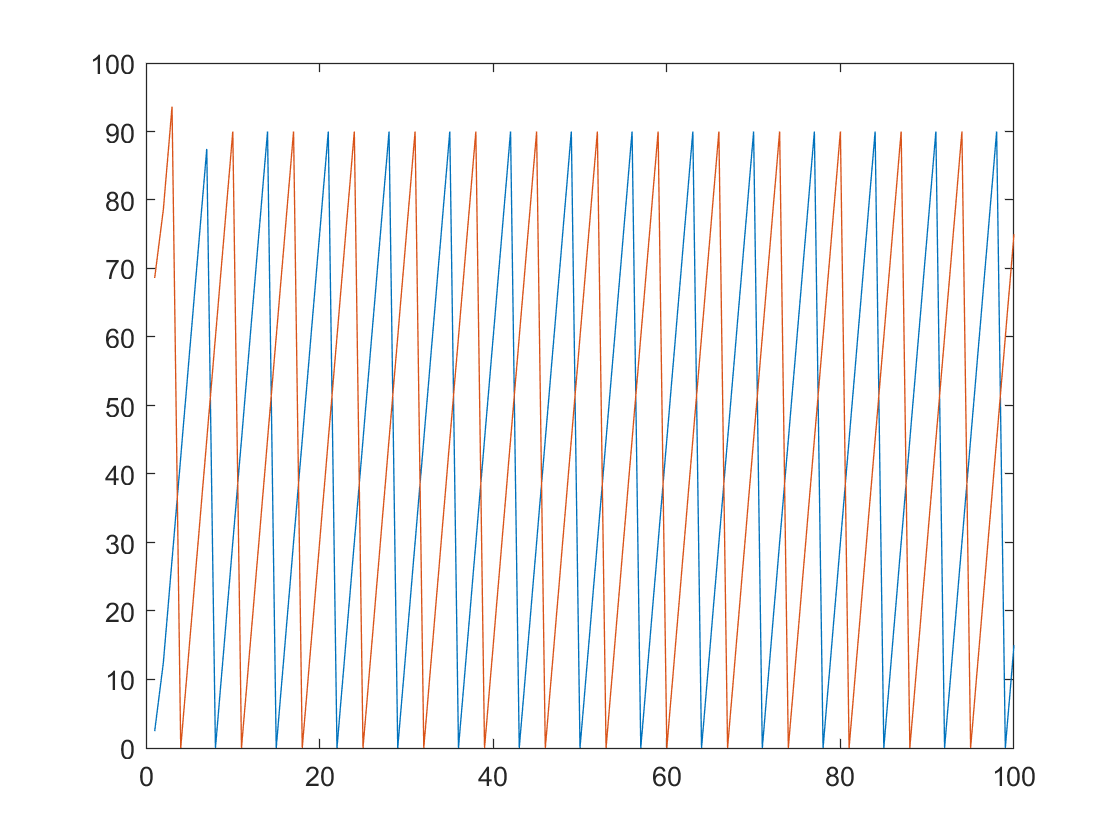

plot(x(2,:));
hold on;
plot(x(4,:));
hold off;

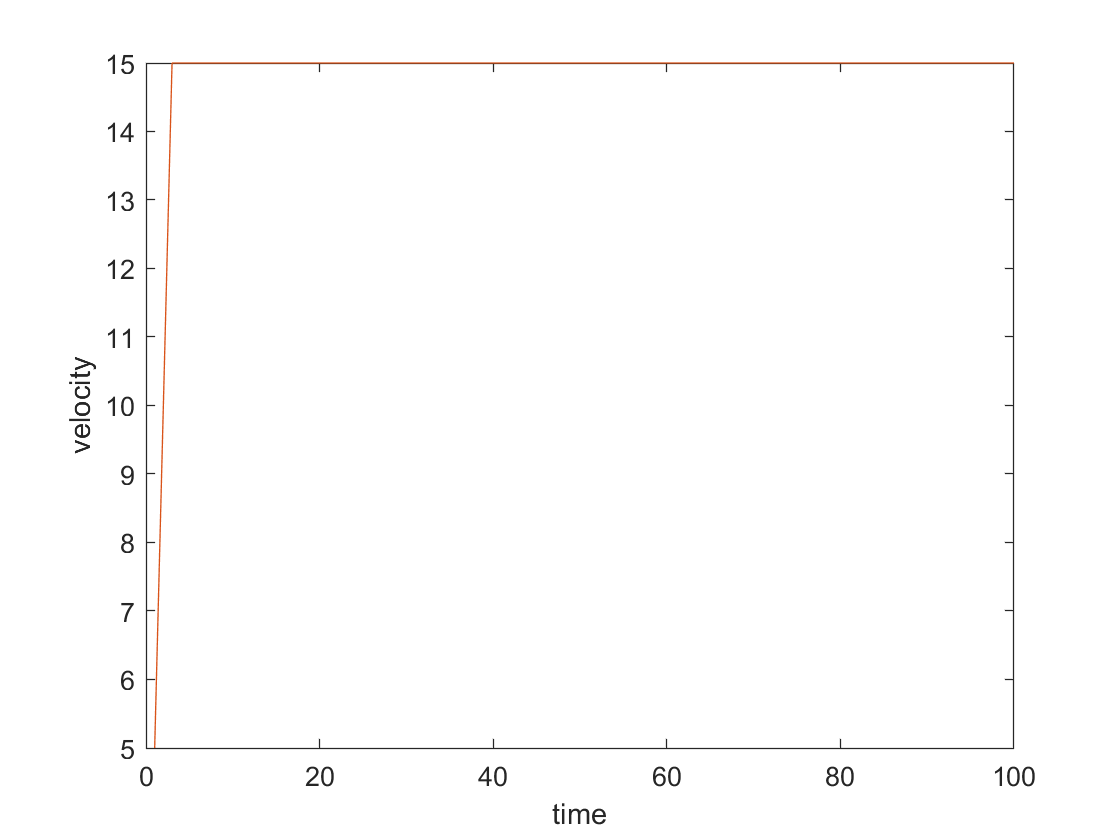

plot(v(2,:));
hold on;
plot(v(4,:));
xlabel('time')
ylabel('velocity')
hold off;

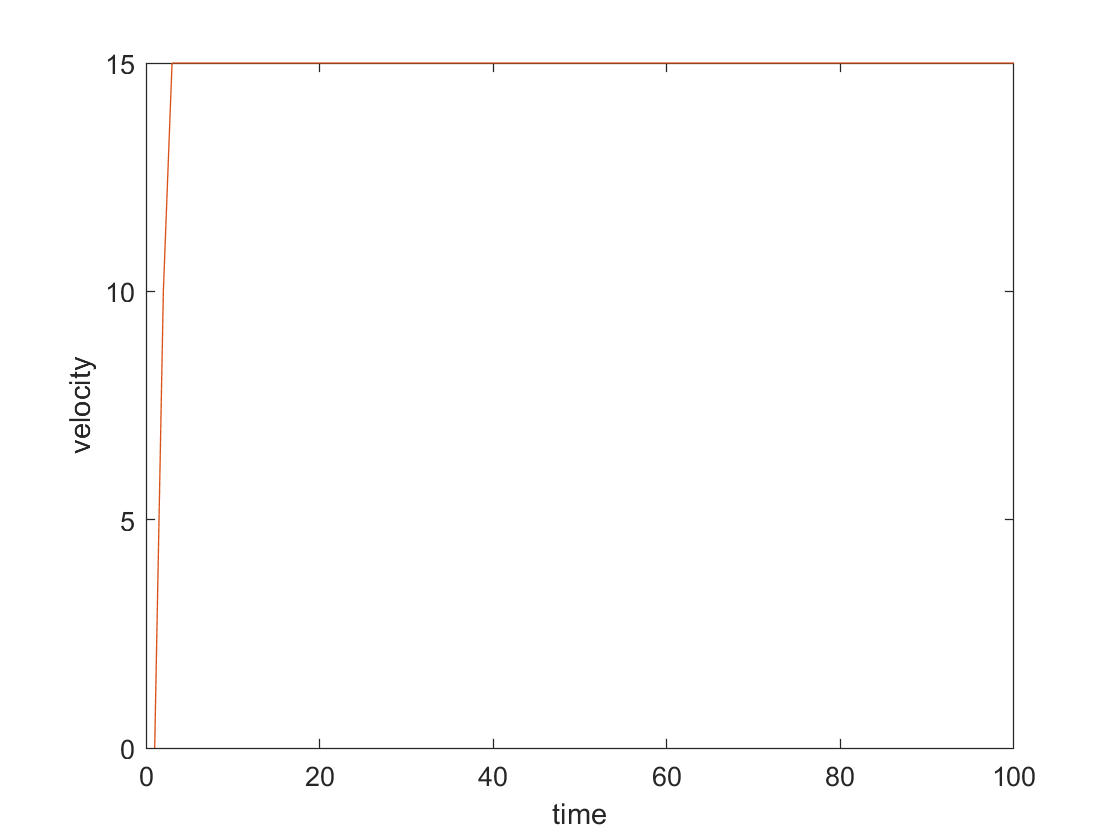

plot(max_speed);
hold on;
plot(min_speed);
xlabel('time')
ylabel('velocity')